## **Dogma demo **

This is a demonstrational script of the Dense Optical Genome Mapping Assembly (DOGMA)

Make sure that SCAMP runs on your system ( [https://scamp-docs.readthedocs.io/en/latest/cli.html#building-the-scamp-cli](https://scamp-docs.readthedocs.io/en/latest/cli.html#building-the-scamp-cli) ). The following command should then work:

pwd;
[~,message] =system('SCAMP --window 5 --input_a_file_name="files/test.txt" --no_gpu --num_cpu_workers=1 --output_a_file_name=test_out --output_a_index_file_name=test_out_mpI --print_debug_info')

message =     'Starting SCAMP
     Validating SCAMP args.
     Building SCAMP Operation from args
     SCAMP Operation constructed
     Num workers = 1
     Precomputing statisics on the CPU.
     Precomputation took 2e-06 seconds.
     num_tile_rows = 1, cols = 1
     Performing join with 1 tiles.
     Main SCAMP thread spawning worker threads.
     Starting tile with starting row of 0 starting column of 0 with height 12 and width 12
     Launching kernel optimized for the platform SCAMP was built on.
     Finished 1 SCAMP tiles to generate  matrix profile in 0.000164 seconds on 0 devices and 1 threads
     Now writing result to files
     Done
     '


## Data input

In this section show how one can generate synthetic data input. The data input are the barcodes corresponding to random fragments of specific genome.

N = 100; % number of random fragments
pxpsf = 2.72; % Gaussian width simulating camera point spread function
mL = 850; % mean length of fragment
stdL = 100; % standard deviation of length of fragment
noise = 2.3;%:0.2:2; % signal to noise ratio
stdE = 0.1; %0.02; % fragment length-rescale factor standard deviation
isC = 1; % yes/no whether the barcode is circular 
tL = 10000; % rand length in px
minL = 150; % minimum length

%% Some sample e-coli sequences were copied using this script (uniqueSpeciesNames were preloaded):
% sequences = dir('/export/scratch/albertas/download_dump/single/*.fasta');
% seqNameToTest = 'Escherichia coli';
% idSeq = find(cellfun(@(x) isequal(x,seqNameToTest),uniqueSpeciesNames)); % need to have species names
% allSeqA = find(idSpecies==idSeq);
% numel(allSeqA)
% arrayfun(@(x) copyfile(fullfile(sequences(allSeqA(x)).folder,sequences(allSeqA(x)).name),...
%     '/home/avesta/albertas/reps/bargroupingprototype/files/'),1:10);
sequences = dir('files/*.fasta');
seqID = 1;


import Core.load_synth_data;
[bgAll, bG, synthStr, synthStr2, theoryStruct] = load_synth_data(N, pxpsf, mL, stdL, ...
    noise, stdE, isC, tL, minL,seqID,sequences );

## Quality of input data

The input data should have a quality control before being passed through DOGMA. Given the theory sequence, we can estimate the SNR level as the ratio of variances of signal/noise. In practical cases, we might not know overall intensity (i.e. data averaged over different number of time frames/taken at different intensities). In that case we would calculate snr_z.  For the synthetic data, we have the theoryStruct so we can perform this directly. For the de novo this would not be available, but from the experiments, the lambda_bg (Poisson parameter of the background) could be known. Also, we might compare to the database to find the closest match and it's SNR.

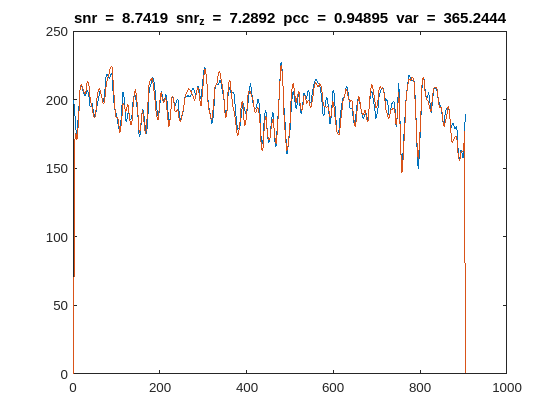

% calc coef to theory (at best extension)
k =7;

% extract barcode and reference
EXTRA_PX = round(6*pxpsf);
re = [zeros(1,EXTRA_PX)  bG{1}{k}.rawBarcode zeros(1,EXTRA_PX) ];
rebB = [zeros(1,EXTRA_PX) bG{1}{k}.rawBitmask zeros(1,EXTRA_PX) ];
reb = rebB(round(linspace(1, length(rebB), round(length(rebB)*synthStr{1}{k}.bestBarStretch))));
re = interp1(re, linspace(1, length(re), round(length(re)*synthStr{1}{k}.bestBarStretch)));
re = re(EXTRA_PX+1:end-EXTRA_PX);
reb = logical(reb(EXTRA_PX+1:end-EXTRA_PX));

if  synthStr{1}{k}.or == 2
    re = fliplr(re);
    reb = fliplr(reb);
end

refBar = theoryStruct{1}{1}.rawBarcode(synthStr{1}{k}.pos:synthStr{1}{k}.pos+length(reb)-1);

% calculate PCC
pcc = zscore(refBar(reb),1)*zscore(re(reb),1)'/sum(reb);

% calculate SNR
noise1 = refBar-re;
snr = var(refBar(16:end-16))/var(noise1(16:end-16));

rz = zscore(refBar);
noise = rz-zscore(re);
snrZSCORE = var(rz)/var(noise(16:end-16));

figure,plot(refBar)
hold on
plot(re)
title(['snr = ',num2str(snr),' snr_z = ',num2str(snrZSCORE),' pcc = ' num2str(pcc),' var = ', num2str(var(re)) ])

Calculate all overlaps

sF= 0.9:0.01:1.1;
timestamp = datestr(clock(), 'yyyy-mm-dd_HH_MM_SS'); % timestamp for results
sets.numworkers = 30;
sets.minOverlap = 300;


tic
[oS] = calc_overlap_mp(bG{1}',sF, sets.minOverlap,timestamp,sets.numworkers );
    disp(['All pairwise overlaps calculated in ', num2str(toc), ' sec']);

All pairwise overlaps calculated in 40.9876 sec


Calculate significance


alphaNu1 = 0.09;
alphaNu2 = 0.085;
alphaN1 = 0.42;
alphaN2 = 0.004;
pthresh = 0.051;
nB = N;
sets.scDiffSetting = 0.05;
sets.pxDifSetting = 50;
ixtest = 1; % load the synthetic dataset with 3 islands

barcodeGen = bG{ixtest}';
tS = theoryStruct{ixtest};

oS = oS(1:nB,1:nB);
barcodeGen = barcodeGen(1:nB);

[sortedVals, sortedIds,localScore,partialScore,lenA,lenB,partialLength,pvalLocal,pvalLeftOver, pvalCombined, sortedValsBad, sortedIdsBad] = ...
    calculate_sorted_pvals(oS,sets.minOverlap, alphaNu1, pthresh,[],alphaN1,alphaNu2,alphaN2); %localCCStruct

sortedValsGood = sortedVals(~isnan(sortedVals));
sortedIdsGood  = sortedIds(~isnan(sortedVals));
localScore = localScore(~isnan(sortedVals));


## Investigate single overlaps

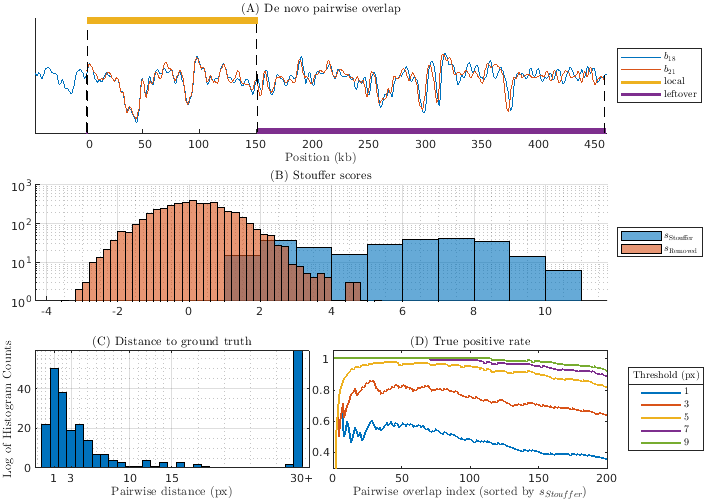

N = length(sortedValsGood);

import Validation.calc_distance_scaled; % need to properly scale things when calculating distances for validation
posShift = calc_distance_scaled(oS,sortedIdsGood(1:N), synthStr{ixtest},theoryStruct{ixtest}{1}.length, N);

N = min(1000,length(sortedIdsBad));

import Validation.calc_pos_dif;
posShiftBad = calc_distance_scaled(oS,sortedIdsBad(1:N), synthStr{ixtest},theoryStruct{ixtest}{1}.length, N);

f=figure('Position', [10 10 714 500]);g=tiledlayout(3,2,'TileSpacing','tight','Padding','none');


idxPair = 1;
[curSink,curSource] = ind2sub(size(oS),sortedIds(idxPair));
import Plot.pair_evaluation_with_ground_truth_simple_plot; % todo: convert comparisonStructC to overlap for this plot (using something like synth_to_struct)
pair_evaluation_with_ground_truth_simple_plot(barcodeGen, oS,curSink,curSource,[],theoryStruct{ixtest}{1}.length,g);


import Plot.position_evaluation_stouffer;
[f,g] = position_evaluation_stouffer(sortedValsGood,sortedValsBad, localScore,posShift,posShiftBad,f,g);



[sum(posShift>30)/length(posShift) mean(posShift(posShift<30)) std(posShift(posShift<30))]

ans =     0.2243    3.8039    4.5649


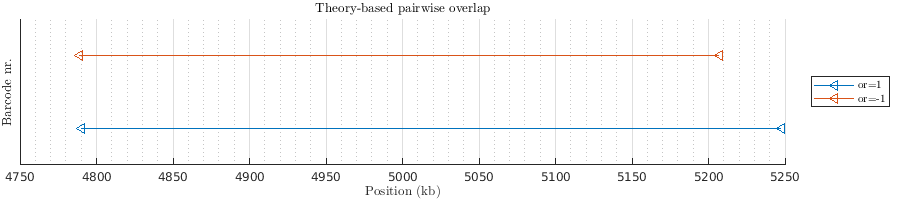


f=figure('Position', [10 10 900 200]);g=tiledlayout(1,2,'TileSpacing','tight','Padding','none');

import Plot.pair_evaluation_ground_truth; % todo: convert comparisonStructC to overlap for this plot (using something like synth_to_struct)
pair_evaluation_ground_truth(barcodeGen, oS,curSink,curSource,synthStr{ixtest},theoryStruct{ixtest}{1}.length,g);

## Calculate barcode islands and overlap graph 


% import Core.barcode_island_output;
[barsetGen, outConsensus, coverage, consensus, islandElts, islandPx,cGenAll,barcodeIslandsData, barStruct,barIslands] =...
    Core.barcode_island_output(sortedValsGood,sortedIdsGood, oS, barcodeGen,timestamp,sets.scDiffSetting,sets.pxDifSetting, [],0,3);

% import Core.create_graph_from_barsetgen;
[Gtemp,GtempOrig] =   Core.create_graph_from_barsetgen(barsetGen,barcodeGen,[],0);


## Overlap graph

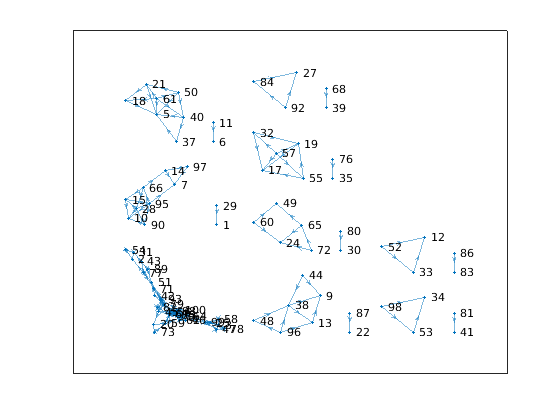

figure
h=plot(Gtemp,'Layout','force','ArrowSize',5,'MarkerSize',1);

% 
h.NodeLabelMode = 'auto';

Create consensus and iterative readjustment

wminC = 300;
NN = 5;

import Core.barcode_island_consensus;
aaBarcodeIslandBlockRep = cell(1,length(cGenAll));
clusterBarcodes =  cell(1,length(cGenAll));
matRep =  cell(1,length(cGenAll));
consensusNew =  cell(1,length(cGenAll));
barCon =  cell(1,length(cGenAll));
stats =  cell(1,length(cGenAll));
cIt =  cell(1,length(cGenAll));

parfor ix = 1:length(cGenAll)
%     ix
    [aaBarcodeIslandBlockRep{ix}, ~,~,clusterBarcodes{ix},~] = barcode_island_consensus(barcodeGen,cGenAll, ix, wminC,[],alphaNu1);

%     NN = 5;
    % wminC
    [matRep{ix},consensusNew{ix},barCon{ix},stats{ix},cIt{ix}] = iterative_readjustment_consensus(aaBarcodeIslandBlockRep{ix},barcodeGen, barIslands, cGenAll,ix,wminC,NN,alphaNu1);

end

Starting comparing exp to theory...
Starting comparing exp to theory...
Starting comparing exp to theory...
Starting comparing exp to theory...
Starting comparing exp to theory...
Starting comparing exp to theory...
Experiments were compared to theory in 0.012977 seconds
Starting comparing exp to theory...
Experiments were compared to theory in 0.012954 seconds
Starting comparing exp to theory...
Experiments were compared to theory in 0.012591 seconds
Starting comparing exp to theory...
Experiments were compared to theory in 0.012092 seconds
Starting comparing exp to theory...
Experiments were compared to theory in 0.013075 seconds
Experiments were compared to theory in 0.027719 seconds
Starting comparing exp to theory...
Experiments were compared to theory in 0.04455 seconds
Starting comparing exp to theory...
Experiments were compared to theory in 0.053831 seconds
Starting comparing exp to theory...
Experiments were compared to theory in 0.024432 seconds
Starting comparing exp to the

## Validation of barcode islands

sets.comparisonMethod = 'mass_pcc';
bT{1}.rawBitmask = ones(1,length(tS{1}.rawBarcode));
import Validation.scaled_pdif_vs_theory;
[val,sorti,valRes] = scaled_pdif_vs_theory(bT,tS{1},barcodeGen,cellfun(@(x) x{end}.idx,cIt,'UniformOutput',false),cellfun(@(x) x{end}.vals,cIt,'UniformOutput',false),sF,sets);

outConsensus = cellfun(@(x) x{end},matRep,'un',false);
% f = figure;
f=figure('Position', [10 10 714 1000]);
tiledlayout(length(outConsensus)+1,3,'TileSpacing','compact','Padding','none')



maxConsensus = max(cellfun(@(x) size(x,2),outConsensus));
% hold on

lettersAll = mat2cell('A':'Z',1,ones(1,26));

letters = lettersAll(1:end)

letters = 1×26 cell array
    {'A'}    {'B'}    {'C'}    {'D'}    {'E'}    {'F'}    {'G'}    {'H'}    {'I'}    {'J'}    {'K'}    {'L'}    {'M'}    {'N'}    {'O'}    {'P'}    {'Q'}    {'R'}    {'S'}    {'T'}    {'U'}    {'V'}    {'W'}    {'X'}    {'Y'}    {'Z'}


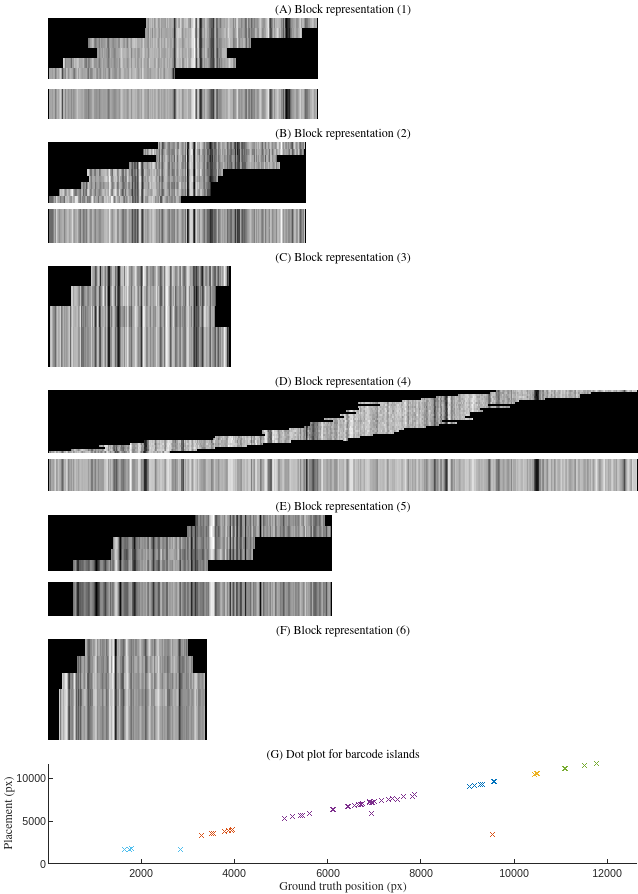

for idx=1:length(outConsensus)
    nexttile([1 3])
    hold on
    title(['(' letters{idx} ') Block representation (', num2str(idx),')'], 'Interpreter','latex')
        
    % sort based on starting position
    [pos,idxv] = sort(arrayfun(@(x) find(~isnan(outConsensus{idx}(x,:)),1,'first') +(find(~isnan(outConsensus{idx}(x,:)),1,'last')-find(~isnan(outConsensus{idx}(x,:)),1,'first'))/2,1:size(outConsensus{idx},1)));
    % 
    consensusToPlot1 = outConsensus{idx}(idxv,:);

    consensusBlock  = repmat(mean(consensusToPlot1,'omitnan'),round(size(consensusToPlot1,1)/2),1);
    consensusEmptyBlock  = max(consensusToPlot1(:)).*ones(round(size(consensusBlock,1)/5),size(consensusBlock,2));
    imagesc([consensusBlock;consensusEmptyBlock;consensusToPlot1;]);colormap(gray)
    ylim([0.5 size([consensusBlock;consensusEmptyBlock;consensusToPlot1;],1)+0.5])
%     text(size(consensusBlock,2)+10,size(consensusBlock,1)/2, 'Consensus','FontSize',10, 'FontName','Times',   'Color','black')
    axis off

    set(gca,'xtick',[])
    text(-650,size(consensusBlock,1)/2, 'Consensus','FontSize',7, 'FontName','Times',   'Color','black')

    xlim([1 maxConsensus])
end

nPixels = 1e5/500;% 500bp/px ;
x = [maxConsensus-nPixels-2020 maxConsensus-2020];
% x=[1 200]
y = [20.6 20.6 ]+30;
plot(x+100,y+30,'Linewidth',2,'Color','white')
% text(x(1),y(1)+0.1, '10 $\mu m$','FontSize',12, 'Color','white','Interpreter','latex')
text(x(1)+nPixels/10,y(1)+40, '100 kb','FontSize',8, 'FontName','Times',   'Color','white')


    nexttile([1 3])

%     par = {'x','o','|',      };% nexttile
hold on
for idx=1:length(val)
    
    plot(valRes{idx}.posTrue,valRes{idx}.bbSAll(:,1),'x');xlabel('Ground truth position (px)','Interpreter','latex');ylabel('Placement (px)','Interpreter','latex');
    xlim([1 length(theoryStruct{ixtest}{1}.rawBarcode)])
end
    title(['(', letters{length(val)+1},') Dot plot for barcode islands'],'Interpreter','latex');


set(gcf, 'Color', 'w')
